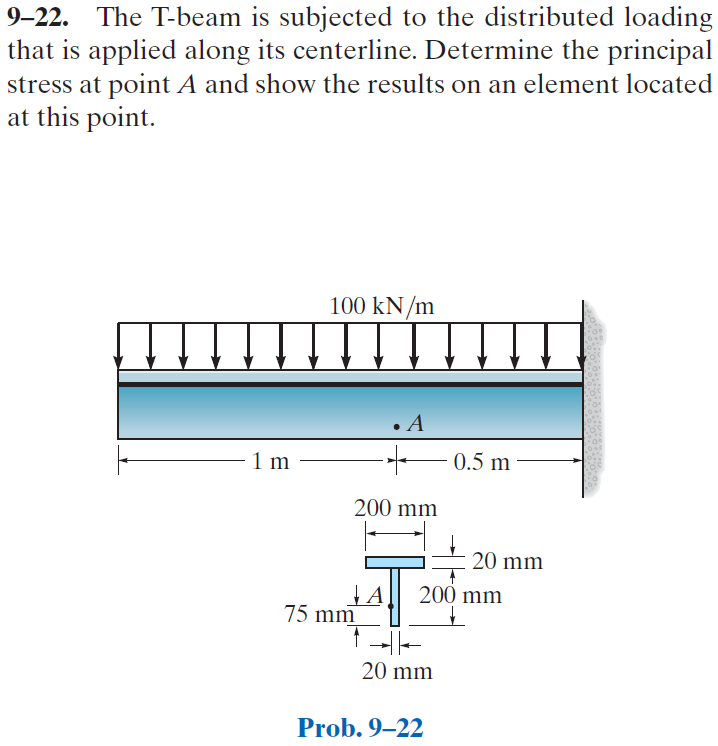

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-22P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-9-problem-22P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'R', 1.5*u.m);
b = b.add('reaction', 'moment', 'M', 1.5*u.m);
b = b.add('distributed', 'force', -100*u.kN/u.m, [0 1.5]*u.m);
b.L = 1.5*u.m;

# section properties

yc = [75/2; 75+(200-75)/2; 200+20/2]*u.mm;
Ac = [20*75; 20*(200-75); 200*20]*u.mm^2;
Ic = [20*75^3; 20*(200-75)^3; 200*20^3]*u.mm^4/12;
[yn Qn In] = beam.neutral_axis(yc, Ac, Ic);
b.I = rewrite(sum(In), u.m);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = -\frac{781250\,{\left(2\,x-3\,m\right)}^{2}\,\left(4\,x^{2}+12\,x\,m+27\,m^{2}\right)}{113\,\text{E}}\,\frac{\mathrm{kN}}{m^{5}}$$

dy

$$dy(x) = -\frac{6250000\,\left(2\,x-3\,m\right)\,\left(4\,x^{2}+6\,x\,m+9\,m^{2}\right)}{113\,\text{E}}\,\frac{\mathrm{kN}}{m^{5}}$$

m

$$m(x) = -50\,x^{2}\,\frac{\mathrm{kN}}{m}$$

v

$$v(x) = -100\,x\,\frac{\mathrm{kN}}{m}$$

w

$$w(x) = -100\,\frac{\mathrm{kN}}{m}$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} M & -112.5\,\mathrm{kN}\,m\\ R & 150.0\,\mathrm{kN} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

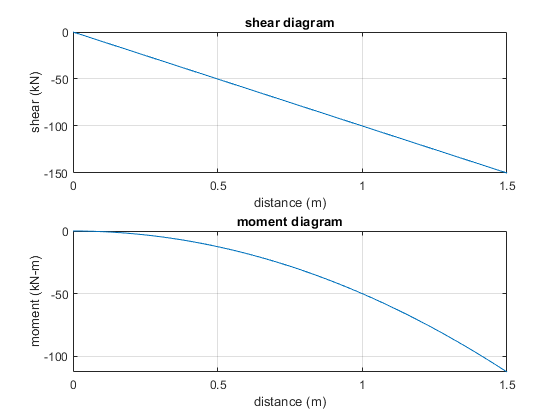

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# loads at point A

M = m(u.m)

$$M = -50\,\mathrm{kN}\,m$$

V = v(u.m)

$$V = -100\,\mathrm{kN}$$

# stresses at point A

% --------------
% bending stress
% --------------
Y = 75*u.mm-yn;
b.I = rewrite(b.I, u.mm);
sigma_bending = rewrite(-M*Y/b.I, u.MPa);
sigma_bending_vpa = vpa(sigma_bending, 5) %#ok<NASGU> 

$$sigma\_bending\_vpa = -106.19\,\mathrm{MPa}$$

% ------------
% shear stress
% ------------
Q = abs(Qn(1));
t = 20*u.mm;
tau_shear = rewrite(-V*Q/(b.I*t), u.MPa);
tau_shear_vpa = vpa(tau_shear, 4) %#ok<NASGU> 

$$tau\_shear\_vpa = 23.4\,\mathrm{MPa}$$

# mohr stresses at point A

sigmax = sigma_bending;
sigmax_vpa = vpa(sigmax, 5) %#ok<NASGU> 

$$sigmax\_vpa = -106.19\,\mathrm{MPa}$$

sigmay = sym(0);
tauxy = tau_shear;
tauxy_vpa = vpa(tauxy, 4) %#ok<NASGU> 

$$tauxy\_vpa = 23.4\,\mathrm{MPa}$$

[sigmaxp sigmayp tauxyp thetap] = beam.principal(sigmax, sigmay, tauxy);
[sigmaxs sigmays tauxys thetas] = beam.max_shear(sigmax, sigmay, tauxy);

# mohr's circle

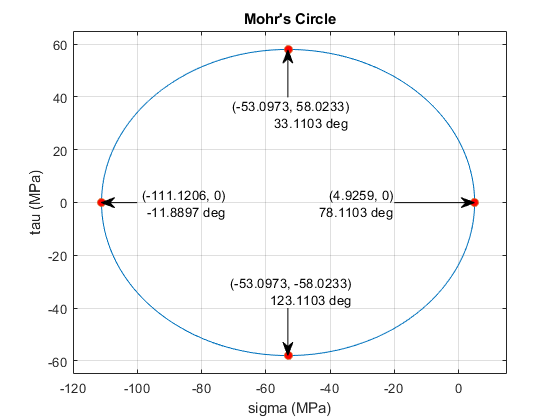

beam.mohr_plot(sigmax, sigmay, tauxy, {'MPa'});
axis([-120 15 -65 65]);
xvals = double(separateUnits([sigmaxp sigmaxs]));
yvals = double(separateUnits([tauxyp tauxys]));
thetavals = double(separateUnits([thetap thetas]));
hold on;
plot(xvals, yvals, 'o', 'MarkerFaceColor', 'r');
for k = 1:4
  switch k
    case 1
      x1 = -100;
      y1 = 0;
    case 2
      x1 = -20;
      y1 = 0;
    case 3
      x1 = xvals(3);
      y1 = 40;
    case 4
      x1 = xvals(4);
      y1 = -40;
  end
  [x1 y1] = ds2nfu(x1, y1);
  [x2 y2] = ds2nfu(xvals(k), yvals(k));
  text_str = {['(' num2str(xvals(k)) ', ' num2str(yvals(k)) ')']
              [num2str(thetavals(k)) ' deg']};
  annotation('textarrow', [x1 x2], [y1 y2], 'String', text_str);
end

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa;
clear sigma_bending_vpa tau_shear_vpa;
clear sigmax_vpa tauxy_vpa;
clear xvals yvals thetavals k x1 y1 x2 y2 text_str;